# Multi-species Population Models: Prey Predator Models

**Mathematical skills:** arithmetics, equations, functions, graphs

**Coding extras:** Tables, solving systems of differential equations with conditions, plots, assigning values, symbolics 

**Task: **Read the intro. Then, modify the code to answer the questions in the Questions section. 

**Criteria**: This lesson is packed, so you might be wondering what do I really need to know after completing it? Here are some checkboxes to guide you:

- Can you change the parameters in the model, `a, b, c, `and` d` as requested in the Questions section?

- Can you qualitatively describe what you see in the prey predator graphs?

- Can you say what the `ode45` function is used for in 3 or 4 words?

If you answered a confident 'yes' to these, you're all set! Good job. If the answer was less confident, try finding the sticky parts and let your instructor know. Pace check is always nice.

## Intro

In the models that we have studied so far, we only thought about one population in isolation. That might work for bacteria grown in a lab, but in most scenarios in wildlife, many species interact in complex ways within an environment. These interactions may affect how their populations change with time. Predation is one of these interesting interactions that leads to certain patterns that are evident in graphs.  

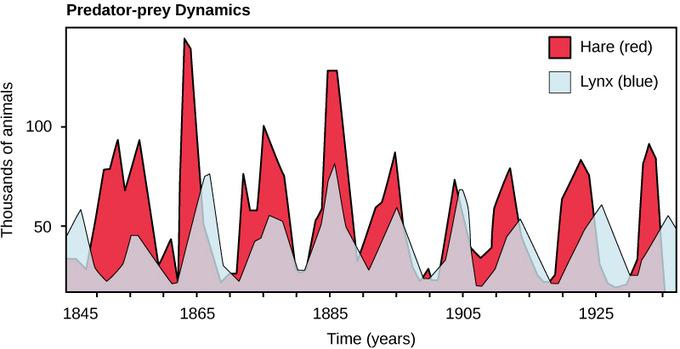

Figure 1: taken from Bio.libretexts.org. This graph of the hare and lynx populations is a famous example of prey-predator population oscillations in the real world created from population counts each year.

    One of the simplest models that captures these patterns starts with the following assumptions:

- `T`he prey grow in an unlimited way when predators do not keep them under control.

- The predators cannot survive without the prey.

- The rate of predation depends on how often a predator encounters a prey.

- The growth rate of the predators depend on their rate of predation (how often they consume the prey).

Putting these assumptions together, we have the prey-predator model which consists of two equations, one corresponding to the prey population and one to the predator population.

$\frac{\textrm{dx}}{\textrm{dt}}=\textrm{ax}-\textrm{bxy},$                                      Equation 1a (prey)

$\frac{\textrm{dy}}{\textrm{dt}}=-\textrm{cy}+\textrm{dxy}$,                            Equation 1b (predator)

where x and y denote prey and predator respectively. So far, we only dealt we differential equation systems that consisted of *one equation*. Here, we have a system of differential equations that consists of two. More specifically, these are called *ordinary differential equations (ODE)* since the only independent variable is t, or time. As the models get more complex, solving them *analytically* becomes more difficult and in some cases impossible. Instead, we solve them numerically. `ode45 `is a MATLAB numerical solver that can solve systems of ordinary differential equatons in a lot of cases.

## Code

 Before using the ode45 function to solve Equation 1, we set the parameters, `a, b, c`, and `d`. Modifying these parameters is what you will be assessed on later.

a = 10; %units: per year 
b = 0.001; %units: per year
c = 5; %units: per year
d = 0.001; %units: per year

Now we choose the time interval that we are interested in, [0 T_final]: 

T_final = 10; %units: years

Depending on the species that we are applying this model to, the units of time here could be hours, days, weeks, years, etc. For the mammals above, years would make the most sense in this example. 

We also set the initial population number for the two populations. In a real world application, this could be the most recent population count. 

initial_prey_population = 10000;

initial_predator_population = 5000;

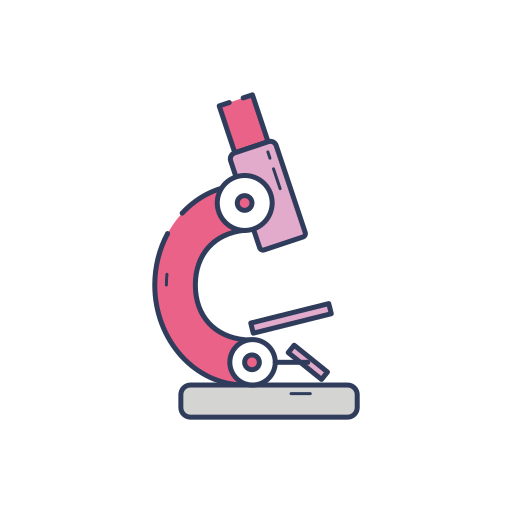**Optional reading**: This section involves some details that you will not be tested on but might find helpful to read. 

Here, we set the settings for the ode solver, `ode45`. Just like a laundry machine where you can choose the temperature of the water and other preferences, we can do the same here! Excep that instead of water temperature, we set an error tolerance with '**RelTol'** (roughly speaking, it determines the number of 'correct' digits in the solution). The second input, '**NonNegative**', tells `ode45` what components of the solution should be non-negative. Since the solution to this set of equations is population number and negative population doesn't make sense, we specify that both solution components, prey population and predator population must be non-negative. (For example, we can talk about 3 snails, but -3 snails wouldn't make sense).

options = odeset('RelTol', 1e-5, 'NonNegative', [1 2]);

Now we use ode45 to solve Equation 1. We use `[t,pops]` to store the solution where `pops` is an array that contains both prey and predator population solutions in separate columns. 

`@(t,x) preypredator(t,x,a,b,c,d) `is a function (found at the end of this guide in the functions section) that contains Equation 1a, and Equation 1b.

[t,pops] = ode45(@(t,x) preypredator(t,x,a,b,c,d),...
    [0 T_final], [initial_prey_population initial_predator_population], options);


[t2,pops2] = ode45(@(t,x) oscipreypredator(t,x,a,b,c,d),...
    [0 T_final], [initial_prey_population initial_predator_population], options);

## Graphs

Let's visualize the results. We will plot both populations on the same graph:

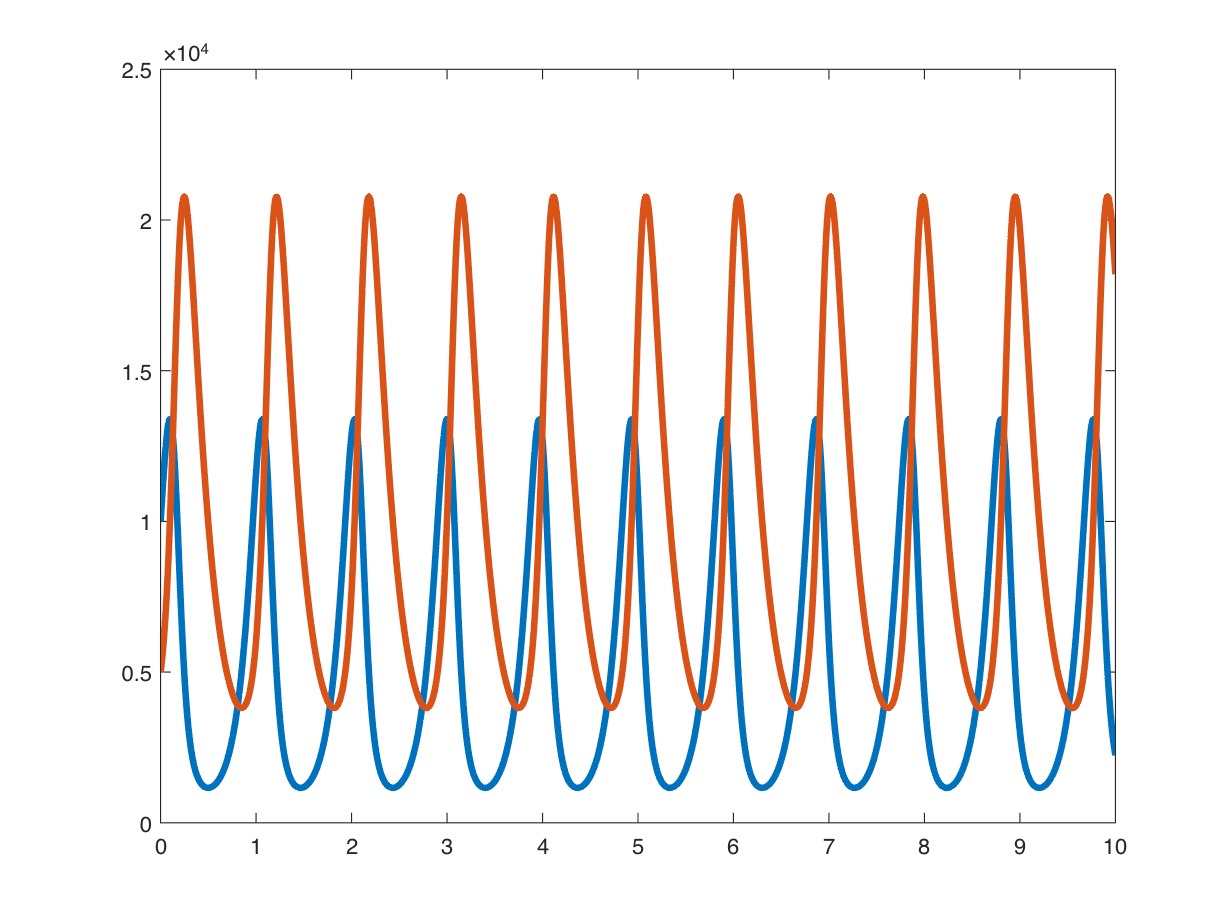

figure
plot(t,pops,'LineWidth', 3);

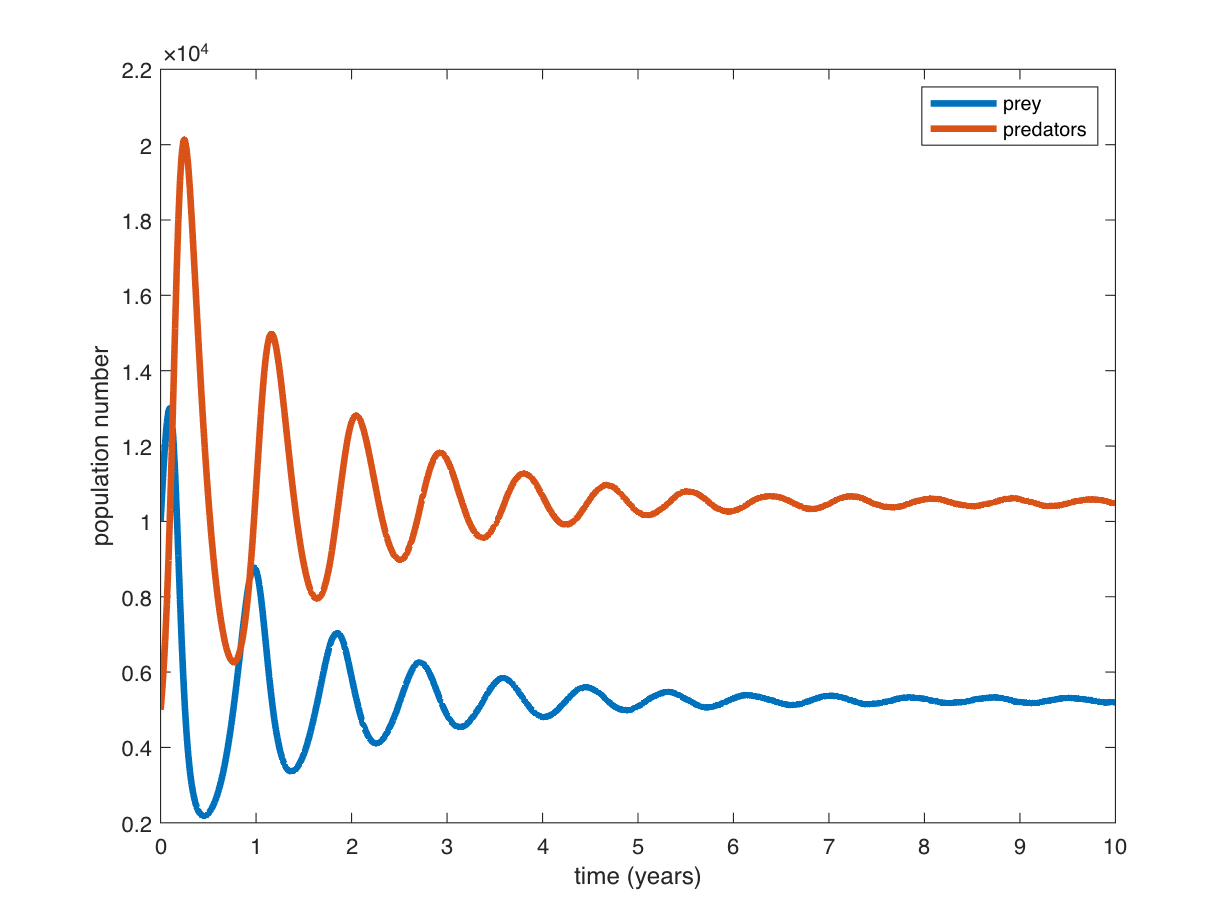

plot(t2,pops2, 'LineWidth', 3)
legend('prey', 'predators');
% insert label for the x-axis
xlabel('time (years)')
% insert label for the y-axis
ylabel('population number')

## Questions

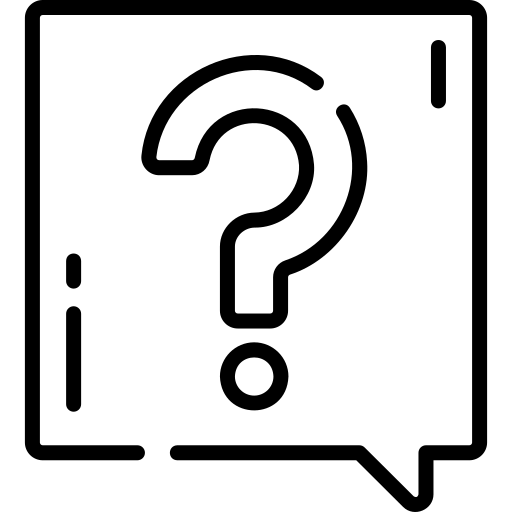 **Question 1:** Play around with the values of a,b,c,d and watch what happens in the graph. What are some possible scenarios?

 **Question 2:** According to the prey-predator model, what happens to the populations when you set b = 0 and d = 0? Why do you think that happens? 

 **Question 3:** Set b = 0 and d = 0. The functions sections in this guide includes the exponential growth model. ( Note: you can also always copy and paste these functions from the functions sections in these guides to use them as you need). We will apply the exponential growth model to the prey population,

ExpModel = ContPopModelExp(a,initial_prey_population);

and plot the results on the same graph as the prey-predator model. Run the entire code. What do you observe in this plot?

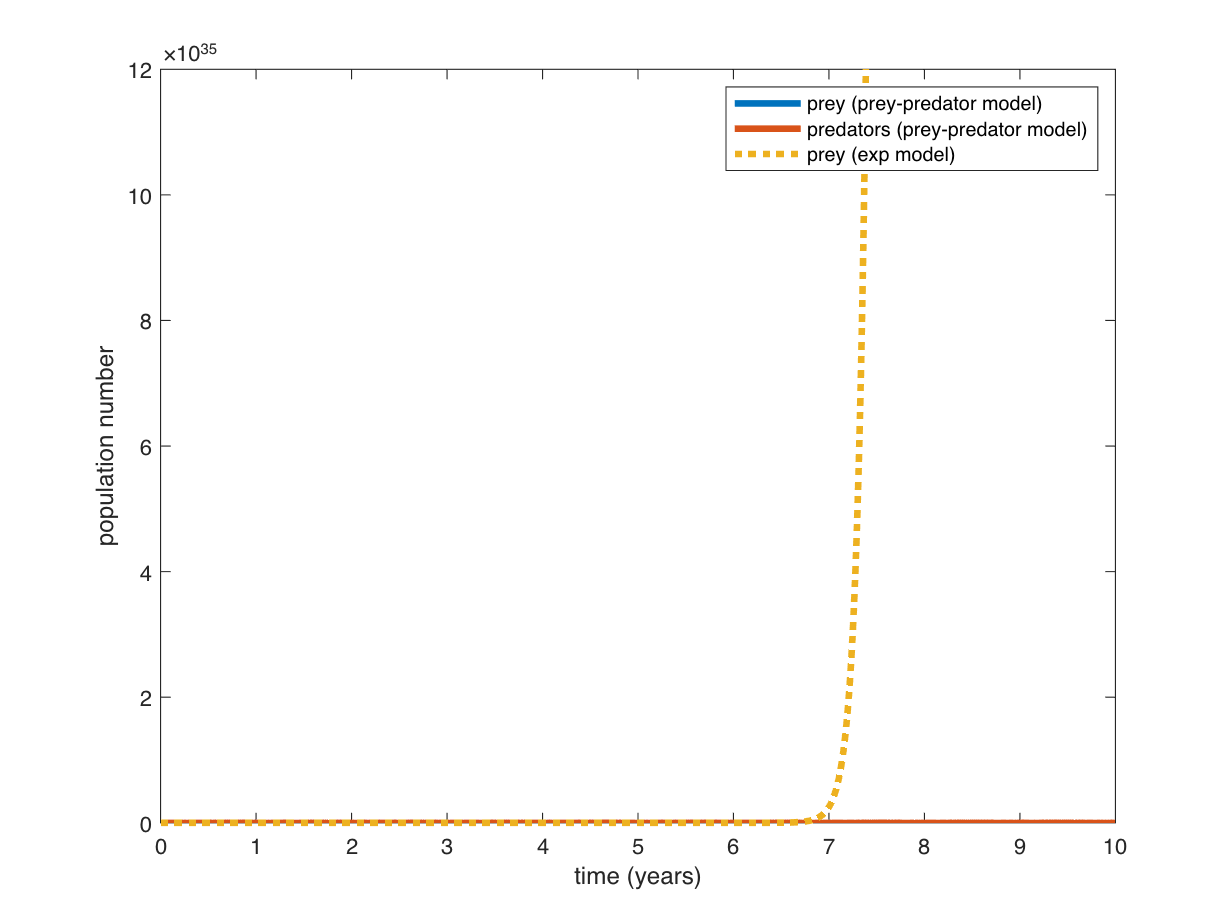

figure
plot(t,pops,'LineWidth', 3);
% insert label for the x-axis
xlabel('time (years)')
% insert label for the y-axis
ylabel('population number')
hold on;
fplot(ExpModel,[0 T_final], 'LineWidth', 3,'linestyle',':', 'DisplayName', 'Exponential Growth')
legend('prey (prey-predator model)', 'predators (prey-predator model)', 'prey (exp model)');

 **Question 4.a:** Set b = 0.001 and d = 0.001, and a = 10 and c = 5. What do you see in the predator-prey graph? 

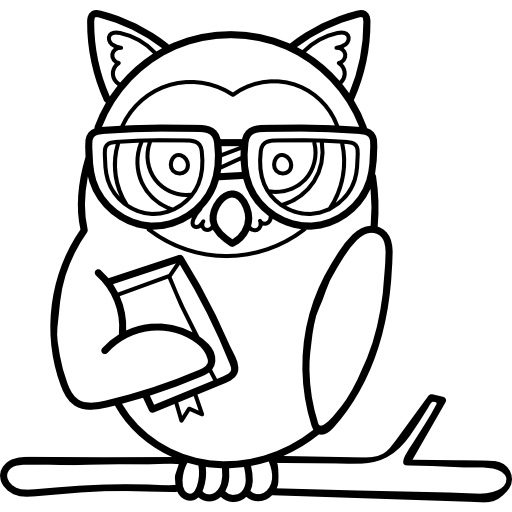  **Owl Note on Question 4: **This is an example of oscillations in nature. We call the time interval from one peak of the oscillating curve to the consequent peak in the curve the **period** of the oscillaton.

 **Question 4.b: **Keep b and d the same but double a and c so that a = 20 and c = 10. What happens to the period of the oscillations?

 **Question 4.c: **Keep b and d the same, and set a = 5 and c = 1. What happens to the period of the oscillations?

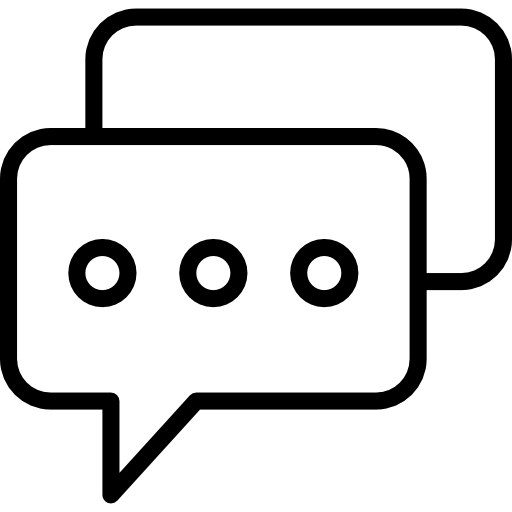 **Question 6:** What concepts are still confusing? What more examples can help? What skills do you need more help with?

 **Question 7:** Can you think of some of the limitations of the prey-predator model?

## Functions

function ExpModel = ContPopModelExp(K,N0)
syms  N(t)
eqn = diff(N, t) == K*N;
cond = N(0) == N0;
ExpModel(t) = dsolve(eqn,cond);

end


%   t - Time variable: not used here because our equation
%       is independent of time, or 'autonomous'.
%   x - Independent variable: this contains both populations (x and y)
% Output:
%   dx - First derivative: the rate of change of the populations
function dz = preypredator(t, z, a, b , c , d)
  dz = [0; 0];
  
  dz(1) = a * z(1) - b * z(1) * z(2);
  dz(2) = -c * z(2)+ d * z(1) * z(2) ;

end


function dz = oscipreypredator(t, z, a, b , c , d)
  dz = [0; 0];
  g = rand;
  f = rand;
  dz(1) = a * z(1) - b * z(1) * z(2) +g*z(2)-f*z(1);
  dz(2) = -c * z(2)+ d * z(1) * z(2) -g*z(2)+f*z(1);

end

## References

***Mathematical Models in Biology*** by **Leah Edelstein-Keshet**

Attributions: Icons are from flaticon.com